% LAB 2
clear
load TRC_display.mat

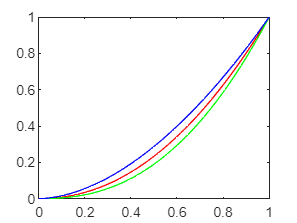

% 1.1
x = 0:0.01:1;
plot(x,TRCr,"Color","red")
hold on
plot(x, TRCg, "Color","green")
plot(x, TRCb, "Color","blue")

% lower value in output, worst for greens then reds

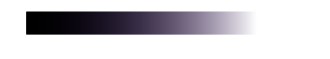

% 1.2
load Ramp_display.mat
load Ramp_linear.mat

imshow(Ramp_display)

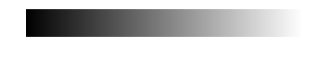

imshow(Ramp_linear)

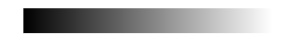

LinearIm = linearize(TRCr, TRCg, TRCb, Ramp_display);

imshow(LinearIm)

% 1.3

yr = 2.1; yg = 2.4; yb = 1.8;
Dmax = max(max(max(Ramp_display)));

Dr = Dmax * (Ramp_display(:,:,1)/Dmax).^(1/yr);
Dg = Dmax * (Ramp_display(:,:,2)/Dmax).^(1/yg);
Db = Dmax * (Ramp_display(:,:,3)/Dmax).^(1/yb);

D(:,:,1) = Dr; D(:,:,2) = Dg; D(:,:,3) = Db;

imshow(D)

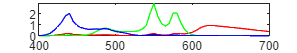

% 2.1 projector spectral sensitivty
clf
load DLP.mat
wl = 400:5:700;
Srmax = DLP(:,1); Sgmax = DLP(:,2); Sbmax = DLP(:,3);
plot(wl,Srmax,"Color","red")
hold on
plot(wl, Sgmax, "Color","green")
plot(wl, Sbmax, "Color","blue")

clf
% Blue channel very good, green channel also vert good but second peak may
% be problematic, red channel very weak

% 2.2 calc projector output for raw camera RGB data for chips
load RGB_raw.mat
load xyz.mat
load XYZ_ref.mat
load illum.mat
Srgb = DLP*RGB_raw;
k = 100 / (CIED65*xyz(:,2));
d = xyz' .* k * Srgb;

% to lab
dlab = zeros(3,20);
XYZ_ref_lab = zeros(3,20);
for i=1:20
    x = d(1,i); y = d(2,i); z = d(3,i);
    [l,a,b] = xyz2lab(x,y,z);
    dlab(:,i) = [l;a;b];

    x =XYZ_ref(1,i); y = XYZ_ref(2,i); z = XYZ_ref(3,i);
    [l,a,b] = xyz2lab(x,y,z);
    XYZ_ref_lab(:,i) = [l;a;b];
end

deltaEab = sqrt((XYZ_ref_lab(1,:)-dlab(1,:)).^2+(XYZ_ref_lab(2,:)-dlab(2,:)).^2+(XYZ_ref_lab(3,:)-dlab(3,:)).^2);
meandiff = mean(mean(deltaEab))

meandiff = 22.3508

maxdiff = max(max(deltaEab))

maxdiff = 51.6380

% 2.3 samma men calibrated rgb data för chips  
load RGB_cal.mat

Srgb = DLP*RGB_cal;
d = xyz' .* k * Srgb;

% to lab
dlab = zeros(3,20);
XYZ_ref_lab = zeros(3,20);
for i=1:20
    x = d(1,i); y = d(2,i); z = d(3,i);
    [l,a,b] = xyz2lab(x,y,z);
    dlab(:,i) = [l;a;b];

    x =XYZ_ref(1,i); y = XYZ_ref(2,i); z = XYZ_ref(3,i);
    [l,a,b] = xyz2lab(x,y,z);
    XYZ_ref_lab(:,i) = [l;a;b];
end

deltaEab = sqrt((XYZ_ref_lab(1,:)-dlab(1,:)).^2+(XYZ_ref_lab(2,:)-dlab(2,:)).^2+(XYZ_ref_lab(3,:)-dlab(3,:)).^2);
meandiff = mean(mean(deltaEab))

meandiff = 16.9236

maxdiff = max(max(deltaEab))

maxdiff = 33.5351

% 3.1
Acrt = k * xyz' * DLP;
% acrt - porjektors input rgb till xyz färger under d65

% 3.2 reproducera hur projektorn visar xyz av chips med acrt
load XYZconvlr.mat
D_prim = inv(Acrt)*XYZconvlr;
Srgb2 = DLP*D_prim;
XYZ_out = k * (xyz' * Srgb2); 
XYZ_ref_lab = zeros(3,20);
XYZ_out_lab = zeros(3,20);

for i = 1:20
    % Convert reference XYZ to Lab
    [l, a, b] = xyz2lab(XYZ_ref(1,i), XYZ_ref(2,i), XYZ_ref(3,i));
    XYZ_ref_lab(:,i) = [l; a; b];

    % Convert predicted projector XYZ to Lab
    [l, a, b] = xyz2lab(XYZ_out(1,i), XYZ_out(2,i), XYZ_out(3,i));
    XYZ_out_lab(:,i) = [l; a; b];
end

% Compute ΔEab color difference
deltaEab = sqrt(sum((XYZ_ref_lab - XYZ_out_lab).^2, 1));
meandiff = mean(deltaEab)

meandiff = 1.0238

maxdiff = max(deltaEab)

maxdiff = 3.1053

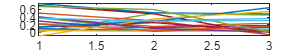

% 3.3
clf
plot(D_prim)

% -0.2 colour? projector cant reproduce these colours

% 3.4

D_clipped = min(max(D_prim, 0), 1);
Srgb_clipped = DLP * D_clipped;
XYZ_clipped = k * (xyz' * Srgb_clipped);

XYZ_clipped_lab = zeros(3,20);
for i = 1:20
    [l, a, b] = xyz2lab(XYZ_clipped(1,i), XYZ_clipped(2,i), XYZ_clipped(3,i));
    XYZ_clipped_lab(:,i) = [l; a; b];
end

deltaEab_clipped = sqrt(sum((XYZ_ref_lab - XYZ_clipped_lab).^2, 1));
meandiff_clipped = mean(deltaEab_clipped)

meandiff_clipped = 2.8360

maxdiff_clipped = max(deltaEab_clipped)

maxdiff_clipped = 17.8740


% removes the neg values but delta lab is higher, maybe better to keep as
% before

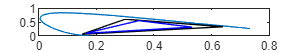

% 3.5
plot_chrom_sRGB(Acrt)

% projector doesnt cover all colours, maybe map values outside projector
% gamut to nearest value in projector gamut

% 3.6 jämför en färgs true spectrum vs projector spectrum
load chips20.mat
% 1 gives smallest deltaeab value
hold off

clf
original =  (chips20.*CIED65)'

original =     0.2529    0.1605    0.0802    0.1131    0.1890    0.1693    0.0250    0.0364    0.0260    0.0234    0.1099    0.0654    0.0721    0.0394    0.2419    0.1120    0.1828    0.0337    0.0522    0.1853
    0.3383    0.1939    0.0930    0.1328    0.2409    0.2160    0.0290    0.0406    0.0308    0.0262    0.1286    0.0739    0.0799    0.0436    0.3387    0.1308    0.2338    0.0387    0.0581    0.2308
    0.4032    0.2200    0.1018    0.1502    0.2840    0.2545    0.0324    0.0466    0.0315    0.0330    0.1438    0.0820    0.0901    0.0487    0.4254    0.1500    0.2791    0.0428    0.0649    0.2657
    0.4596    0.2396    0.1146    0.1669    0.3239    0.2877    0.0401    0.0510    0.0359    0.0351    0.1609    0.0876    0.0973    0.0531    0.4900    0.1658    0.3176    0.0496    0.0722    0.2915
    0.5068    0.2583    0.1240    0.1816    0.3563    0.3187    0.0415    0.0558    0.0414    0.0377    0.1742    0.0931    0.1036    0.0583    0.5476    0.1822    0.3582    0.0529    0

%Sout = k * (xyz' * original)
og_sample = original(:,1)

og_sample =     0.2529
    0.3383
    0.4032
    0.4596
    0.5068
    0.5435
    0.5772
    0.6079
    0.6325
    0.6331


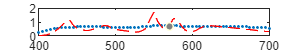

%Sout_sample = Sout(1,:)
plot(wl, og_sample, ['.'])
hold on
plot(wl, Srgb_clipped(:,1), 'r--')
hold off


ref = XYZ_ref_lab(:,1)

ref =    85.6378
    1.3836
   14.6783


repr = XYZ_clipped_lab(:,1)

repr =    85.6322
    1.4123
   14.6950


diff = deltaEab(:,1)

diff = 0.0337


% deltaeab is very small, green colours show very well f.e and reds not as
% well

function linearizedIm = linearize(r, g, b, im)
    x = 0:0.01:1;
    linearizedIm(:,:,1) = interp1(r, x, im(:,:,1), 'pchip');
    linearizedIm(:,:,2) = interp1(g, x, im(:,:,2), 'pchip');
    linearizedIm(:,:,3) = interp1(b, x, im(:,:,3), 'pchip');
end